# GLM

close all;clear;clc;
rng('default')
addpath models\
addpath utils\
load("data/data_rat010_0615_spike_train_selected.mat")

## Grid Search

Predict **7th** neuron

regulization parameter **alpha **almost useless, might be useful when **xi **is lare and **alpha **is quite small(0~0.1). Use 0 first.

H larger likely be better. xi need not explore a lot.

GLM_explore_H = struct( ...
    "H",{}, "xi",{}, "thres",{}, "iterThres",{}, ...
    "maxIter",{}, "alpha",{}, "M1Idx",{}, ...
    "W",{}, "L",{}, "DBR",{} ...
    );
for H=1:20 % Temporal history. Explore within [1:10]
  xi=0.1; % Weights random initial range parameter
  alpha=0; % Regulization parameter
  thres = 1e-3; % stop error tolerance
  iterThres = 7; % stop after error over threshold $ times
  maxIter = 40; % max iteration num, over needs re-initial
  M1Idx = 1; % select M1 neuron
  splitFun = @(history)splitData(mPFCspike,M1spike(:,M1Idx),history); % choose splitData function as first Order
  verbose = 2;
  [W, L, DBR] = runGLM(H, xi, thres, iterThres, maxIter, alpha, splitFun, verbose);
  GLM_explore_H(H) = struct( ...
    "H",H, "xi",xi, "thres",thres, "iterThres",iterThres, ...
    "maxIter",maxIter, "alpha",alpha, "M1Idx",M1Idx, ...
    "W",W, "L",L, "DBR",DBR ...
    );
end

13/40:Train Complete...L:-14512.8585	...H:1	...xi:0.1	...alpha:0
      Test Complete...L:-15906.1425	...DBR:1.1104
13/40:Train Complete...L:-14444.7714	...H:2	...xi:0.1	...alpha:0
      Test Complete...L:-15886.4774	...DBR:1.0608
13/40:Train Complete...L:-14373.0838	...H:3	...xi:0.1	...alpha:0
      Test Complete...L:-15894.7013	...DBR:1.0006
13/40:Train Complete...L:-14309.5116	...H:4	...xi:0.1	...alpha:0
      Test Complete...L:-15881.5739	...DBR:0.95414
13/40:Train Complete...L:-14272.1896	...H:5	...xi:0.1	...alpha:0
      Test Complete...L:-15886.7835	...DBR:0.95411
13/40:Train Complete...L:-14226.7988	...H:6	...xi:0.1	...alpha:0
      Test Complete...L:-15896.25	...DBR:0.94802
13/40:Train Complete...L:-14202.341	...H:7	...xi:0.1	...alpha:0
      Test Complete...L:-15902.2839	...DBR:0.92002
13/40:Train Complete...L:-14187.9798	...H:8	...xi:0.1	...alpha:0
      Test Complete...L:-15922.1014	...DBR:0.8954
13/40:Train Complete...L:-14166.3912	...H:9	...xi:0.1	...alpha:0
      Test Com

save("results\GLM_explore_H.mat", "GLM_explore_H")

## Result analyze

### DBR-history

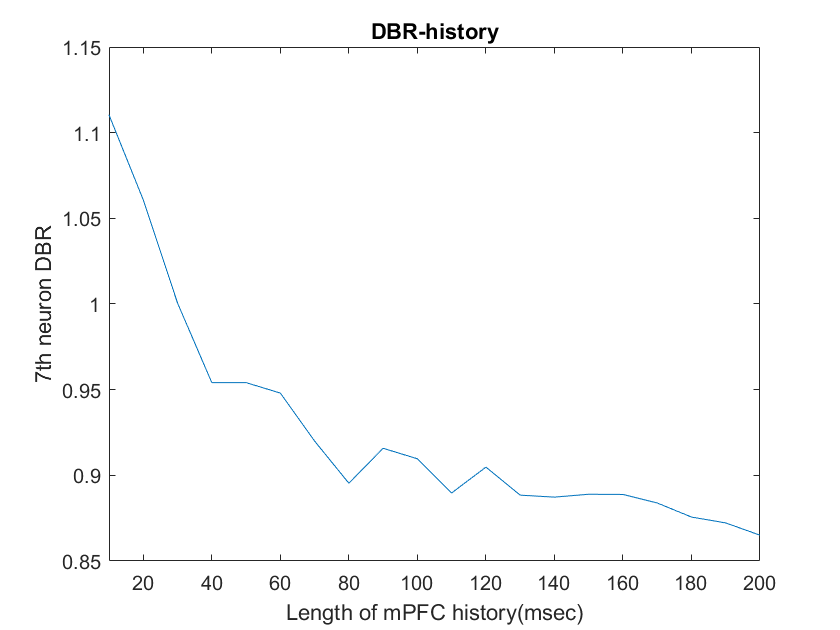

DBR = zeros(1,20);
for i=1:20
  DBR(i) = GLM_explore_H(i).DBR;
end
figure(1)
plot(10:10:200, DBR)
xlabel("Length of mPFC history(msec)")
xlim([10 200])
ylabel("7th neuron DBR")
title("DBR-history")

### firing rate, cc kernel size analyze

Take history=9 for firing rate cc-kernel size analyze, kernel size changes from 10~1000(*10msec)

W = GLM_explore_H(9).W;
H = GLM_explore_H(9).H;
M1Idx = GLM_explore_H(9).M1Idx;
[~,~,testLen,~,~,testX,~,~,testY] = splitData(mPFCspike,M1spike(:,M1Idx),H);
testLambdaYpre = GLMmodel(testX, W);
ccList = zeros(1, 1000/10);
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(testLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  ccList(kernelSize/10) = cc(2);
end

take kernel size=50(0.5s) for plot

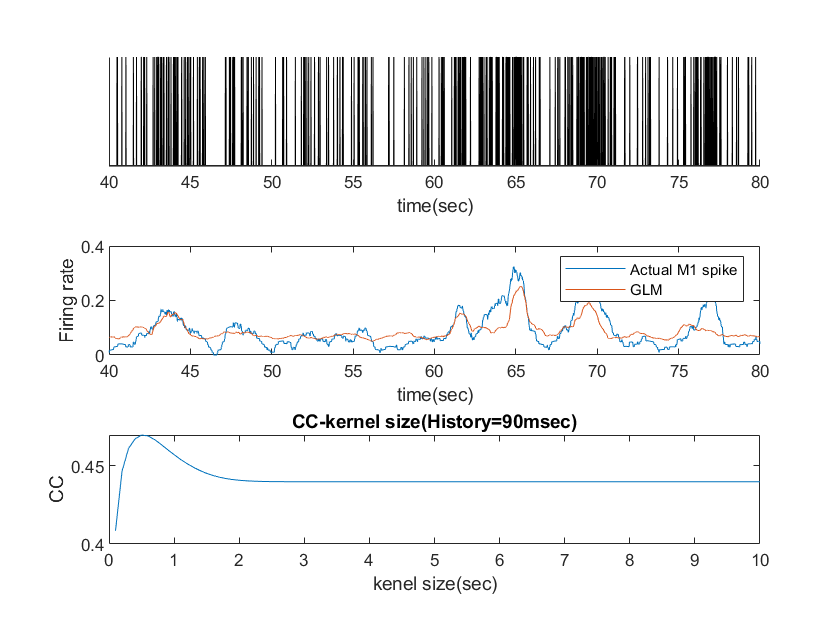

smoothedLambda    = gaussianSmooth(testY, 50);
smoothedLambdaPre = gaussianSmooth(testLambdaYpre, 50);
figure(2)
subplot(3,1,1)
area(40:0.01:80, testY(4000:8000))
xlabel("time(sec)")
set(gca, 'ytick', [])
set(gca, 'box', 'off')
subplot(3,1,2)
plot(40:0.01:80, smoothedLambda(4000:8000))
hold on
plot(40:0.01:80, smoothedLambdaPre(4000:8000))
hold off
xlabel("time(sec)")
ylabel("Firing rate")
legend("Actual M1 spike", "GLM")
subplot(3,1,3)
plot(0.1:0.1:10, ccList)
xlabel("kenel size(sec)")
xlim([0 10])
ylabel("CC")
title("CC-kernel size(History=90msec)")